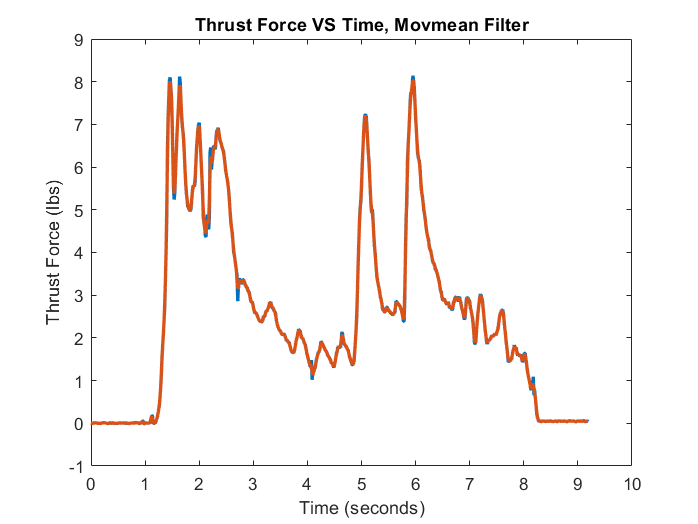

clc;
close all;
clear all;
clearvars;

% import the data from the text file

data_file = sprintf('data.mat');
data = importdata(data_file);
start = 1;

% Get the time, theta, and dtheta from arduino code
datatime = data(start+1:end, 1); %useless
thrustforce = data(start+1:end, 2); 
encoder1angle = data(start+1:end, 3);
encoder2angle = data(start+1:end, 4);

% Define sampling frequency and time vector
fs = 80;  % Hz 
time = (0:length(thrustforce)-1)/fs; 

%movmean converted data vectors

newthrustforce_movmean = movmean(thrustforce,3); %% moving average last three
newencoder2angle_movmean = movmean(encoder2angle,3);
newencoder1angle_movmean = movmean(encoder1angle, 3);

%Movmean Filter (type of builtin moving average)

figure(1);
plot(time, thrustforce, 'LineWidth',2);
hold on;
plot(time, newthrustforce_movmean,'LineWidth',2);
title("Thrust Force VS Time, Movmean Filter");
ylabel('Thrust Force (lbs)');
xlabel('Time (seconds)');
hold off;

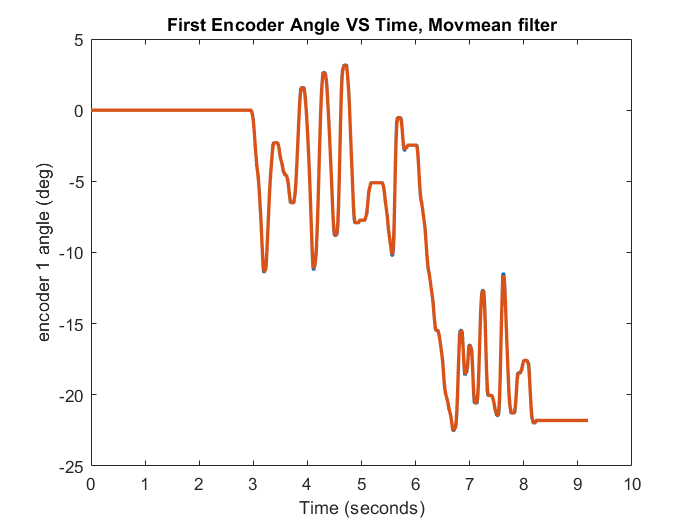


figure(2);
plot(time, encoder1angle, 'LineWidth',2);
hold on;
plot(time, newencoder1angle_movmean, 'LineWidth',2);
title("First Encoder Angle VS Time, Movmean filter");
ylabel('encoder 1 angle (deg)');
xlabel('Time (seconds)');
hold off;

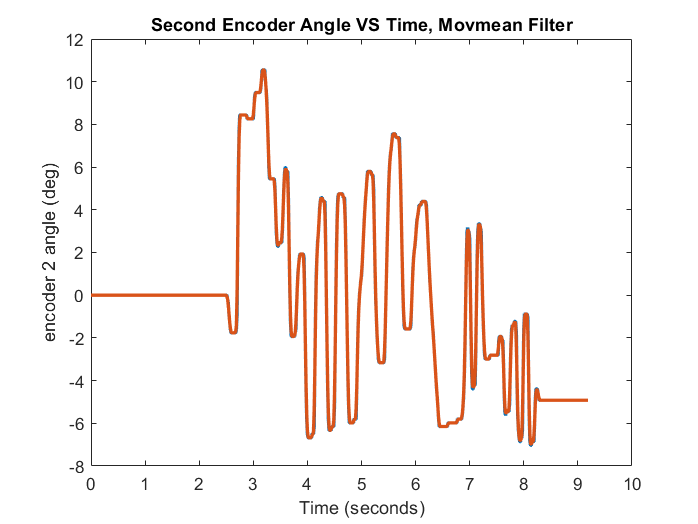


figure(3);
plot(time, encoder2angle, 'LineWidth',2);
hold on;
plot(time, newencoder2angle_movmean, 'LineWidth',2);
title("Second Encoder Angle VS Time, Movmean Filter");
ylabel('encoder 2 angle (deg)');
xlabel('Time (seconds)');
hold off;


% FINDING THE TRANSFER FUNCTION

impulse_hammer_data_file = sprintf('Impulse_Data_Recent.mat');
hammer_data = importdata(impulse_hammer_data_file);

desired_frequency = 80; %Hz, (sampling rate of slowest 
sampling_rate = 1000000 %Hz (look at oscilloscope SPS rate)

sampling_rate = 1000000

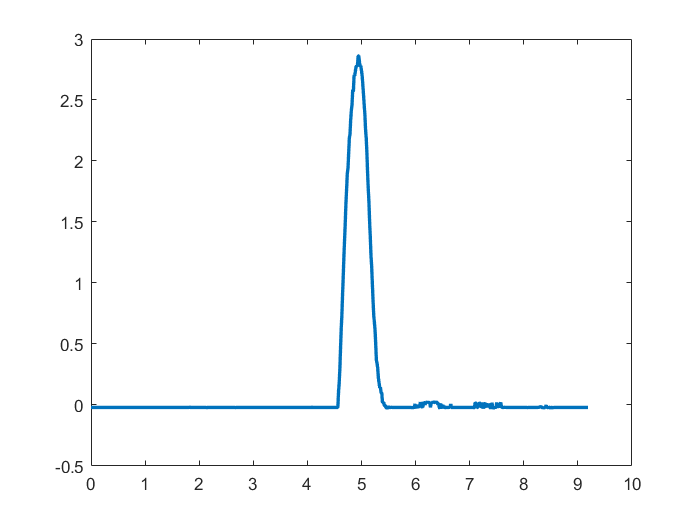

downsampling_factor = round(sampling_rate / 80); 

if length(hammer_data)/downsampling_factor < length(data) % must resample then downsample (otherwise will give less than n number of pts)
    upsampling_factor = (length(data) +(floor((length(data)*downsampling_factor)/length(hammer_data))-length(data)))-1; %% upsample hammer data
    upsampled_hammer_data = resample(hammer_data, upsampling_factor, 1);
    downsampled_hammer_data = downsample(upsampled_hammer_data, downsampling_factor);  %downsample to match 80HZ
else %dont need to resample, just downsample
    downsampled_hammer_data = downsample(hammer_data, downsampling_factor);  %downsample to match 80HZ
end

figure(4); % plot impact hammer wave
hammer_time = (0:length(downsampled_hammer_data)-1)/80;
plot(hammer_time, downsampled_hammer_data, 'LineWidth',2);

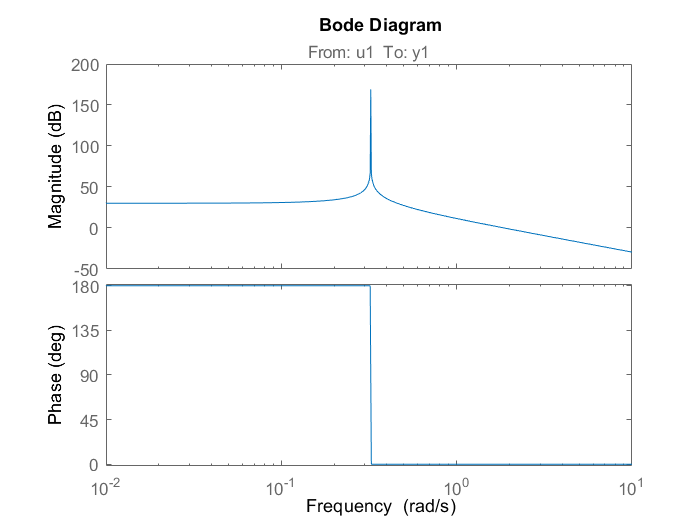


save("downsampled_hammer_data.mat"); %save file

% Design a low-pass filter for the encoder signals
fc = 30; % Hz (Nyquist Frequency)
[b,a] = butter(1, fc/(fs/2), "low");

% Apply the filter to the encoder signals and hammer signal 
hammer_filt = filtfilt(b,a,downsampled_hammer_data);

y1_filt = filtfilt(b,a,newencoder1angle_movmean);
y2_filt = filtfilt(b,a,newencoder2angle_movmean);

% Define the input and output signals with filtered encoder data

y1_filt = iddata(y1_filt, hammer_filt, 1/fs);
y2_filt = iddata(y2_filt, hammer_filt, 1/fs);

% Specify the model structure
sys1 = tfest(y1_filt, 2, 0); %lowest order that caputres order well enough
sys2 = tfest(y2_filt, 2, 0);

% Plot the Bode plot of the transfer function
bode(sys1);

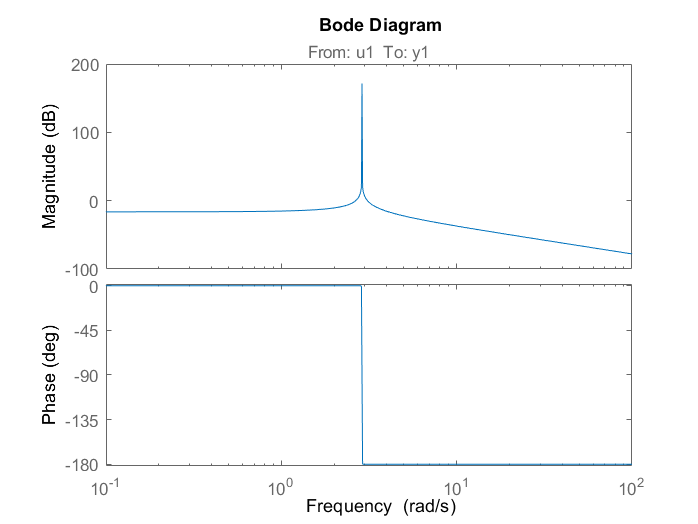

bode(sys2);


disp(sys1);

  idtf with properties:

        Numerator: -3.3836
      Denominator: [1 3.6599e-08 0.1047]
         Variable: 's'
          IODelay: 0
        Structure: [1×1 pmodel.tf]
    NoiseVariance: 0.1820
       InputDelay: 0
      OutputDelay: 0
               Ts: 0
         TimeUnit: 'seconds'
        InputName: {'u1'}
        InputUnit: {''}
       InputGroup: [1×1 struct]
       OutputName: {'y1'}
       OutputUnit: {''}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
     SamplingGrid: [1×1 struct]
           Report: [1×1 idresults.tfest]



disp(sys2);

  idtf with properties:

        Numerator: 1.2692
      Denominator: [1 1.1840e-09 8.3214]
         Variable: 's'
          IODelay: 0
        Structure: [1×1 pmodel.tf]
    NoiseVariance: 0.1841
       InputDelay: 0
      OutputDelay: 0
               Ts: 0
         TimeUnit: 'seconds'
        InputName: {'u1'}
        InputUnit: {''}
       InputGroup: [1×1 struct]
       OutputName: {'y1'}
       OutputUnit: {''}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
     SamplingGrid: [1×1 struct]
           Report: [1×1 idresults.tfest]



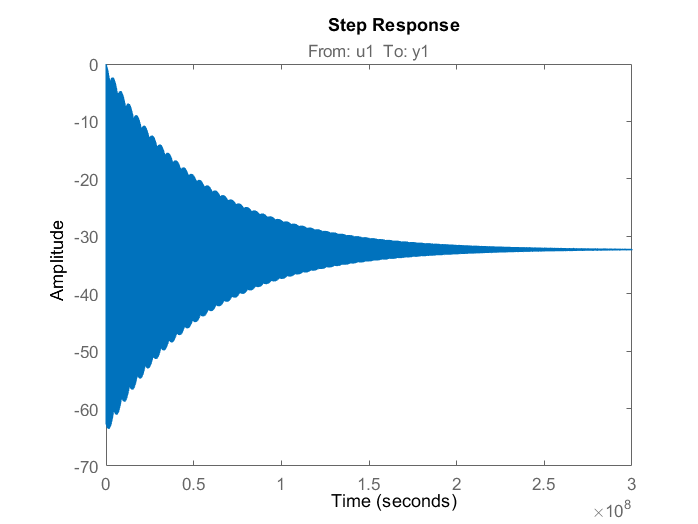


step(sys1)

step(sys2)

grid on;